# Motor Drive Unit - Simulation Case

## Constant input signals

Check that the model runs out of the box.

mdl = "MotorDriveUnit_harness_model";
load_system(mdl)
MotorDriveUnit_harness_setup

Select model to use.

MotorDriveUnit_useRefsub_System

Model: MotorDriveUnit_harness_model
Setting up referenced subsystem: MotorDriveUnit_refsub_System


Load simulation case.

MotorDriveUnit_setSimCase_Constant

Setting up simulation...
Simulation case: Constant inputs
Setting simulation stop time to 1000 sec.
Setting block parameters...
batteryHV.nominalVoltage_V = 340
batteryHV.internalResistance_Ohm = 0.01
Setting initial conditions...
initial.loadInertiaSpd_rpm = 0
initial.motorSpd_rpm = 0
initial.motorDriveUnit_Temperature_K = 293.15
initial.ambientTemp_K = 293.15


Run simulation.

simOut = sim(mdl);

Visually inspect the result.

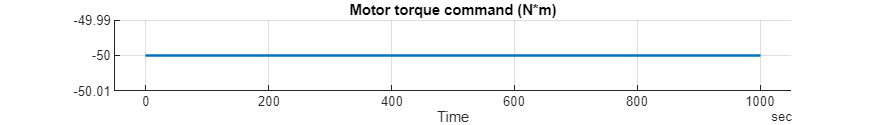

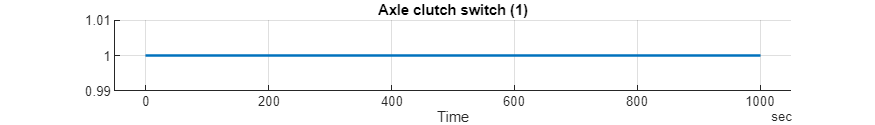

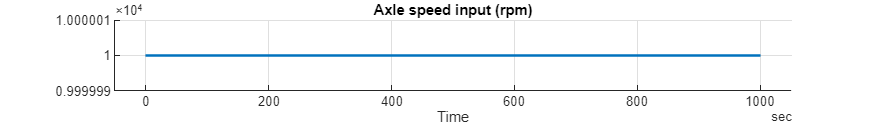

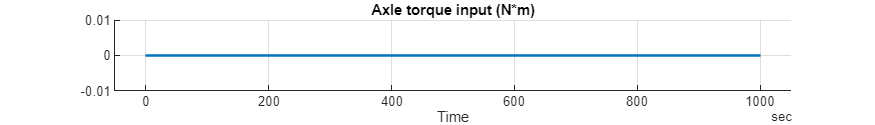

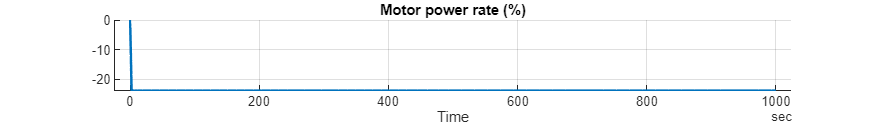

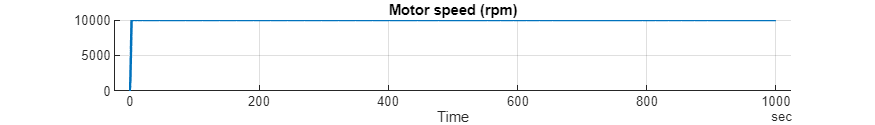

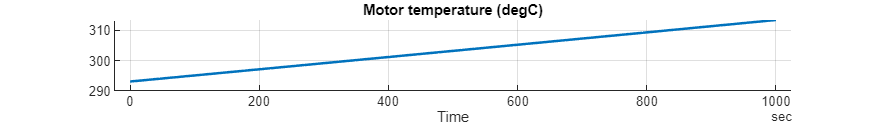

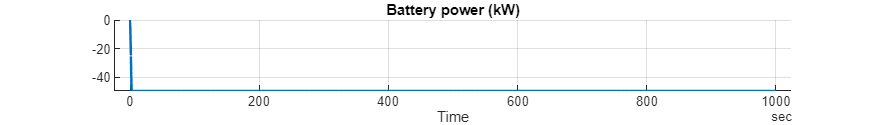

simData = extractTimetable(simOut.logsout);
MotorDriveUnit_ResultsPlot(Timetable=simData, PlotHeight=100);

*Copyright 2021-2025 The Mathworks, Inc.*